%% Step 1: Load the Solar Data from CSV
clc; clear; close all;

% Load the dataset
data = readtable('nasa_solar_large_data.csv');


% Display first few rows
disp('Sample Data:');

Sample Data:


disp(data(1:5, :));

    Latitude    Longitude    Solar_Irradiance_W_m2    Elevation_m    Shading_Factor__
    ________    _________    _____________________    ___________    ________________

     31.112      -122.71            921.65              185.56            18.78      
     37.184      -122.07            750.84              124.22             13.9      
     34.928      -116.11            939.68               79.36             8.51      
     36.539      -121.49            847.84              226.59            11.69      
     37.297      -120.56            762.94                64.2            18.41      



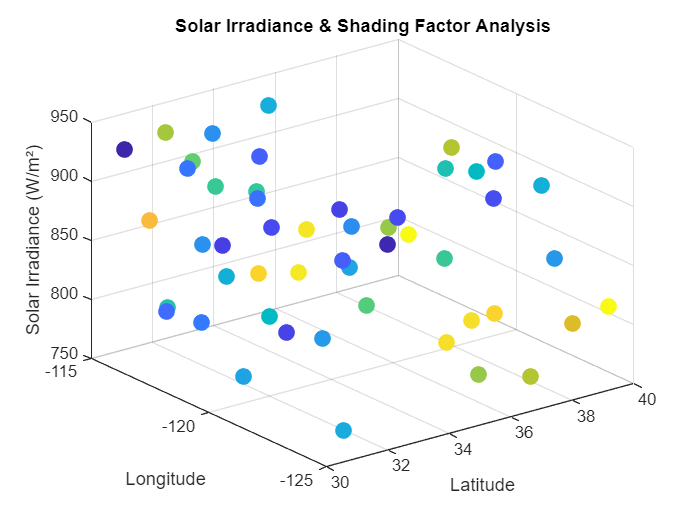


% Extract data columns
latitude = data.Latitude;
longitude = data.Longitude;
solar_irradiance = data.Solar_Irradiance_W_m2;
elevation = data.Elevation_m;
shading_factor = data.Shading_Factor__;

% Compute effective irradiance after considering shading
effective_irradiance = solar_irradiance .* (1 - shading_factor / 100);

%% Step 2: Ensure Reshape Compatibility for Elevation Data
num_points = numel(elevation);
grid_size = round(sqrt(num_points)); % Find closest square size

% Adjust size if necessary
if grid_size^2 ~= num_points
    elevation = elevation(1:grid_size^2); % Trim extra data points if needed
end

% Reshape elevation data into a grid
elevation_matrix = reshape(elevation, grid_size, grid_size);

%% Step 3: Calculate Optimal Tilt Angle Based on Sun Position
function sun_angle = getSunPosition(lat, long, time)
    % Calculate solar declination angle
    day_of_year = day(time, 'dayofyear');
    declination = 23.45 * sind((360/365) * (day_of_year - 81));
    
    % Calculate hour angle
    hour_angle = 15 * (hour(time) - 12);
    
    % Calculate solar elevation angle
    sun_angle = asind(sind(lat) * sind(declination) + cosd(lat) * cosd(declination) * cosd(hour_angle));
end

% Get sun angle for each location
time_now = datetime('now');
sun_angles = arrayfun(@(lat, lon) getSunPosition(lat, lon, time_now), latitude, longitude);

%% Step 4: Optimize Panel Tilt for Maximum Exposure
function optimal_tilt = optimizeTilt(sun_angle, panel_tilt)
    learning_rate = 0.01;
    for i = 1:100
        gradient = 2 * (panel_tilt - sun_angle);
        panel_tilt = panel_tilt - learning_rate * gradient;
    end
    optimal_tilt = panel_tilt;
end

% Compute optimal tilt for each location
initial_tilt = 30; % Assume initial tilt
optimal_tilts = arrayfun(@(x) optimizeTilt(x, initial_tilt), sun_angles);

%% Step 5: Perform Shading Analysis
function shading_factor = analyzeShading(elevation_matrix, panel_location)
    [rows, cols] = size(elevation_matrix);
    panel_x = panel_location(1);
    panel_y = panel_location(2);
    
    shading_factor = 0;
    for i = max(1, panel_x - 5):min(rows, panel_x + 5)
        for j = max(1, panel_y - 5):min(cols, panel_y + 5)
            if elevation_matrix(i, j) > elevation_matrix(panel_x, panel_y)
                shading_factor = shading_factor + 1;
            end
        end
    end
    shading_factor = shading_factor / (10 * 10);
end

% Simulate shading analysis using elevation data
panel_location = [round(grid_size/2), round(grid_size/2)]; % Select a central panel location
shading_result = analyzeShading(elevation_matrix, panel_location);

%% Step 6: Visualize the Data and Results
figure;
scatter3(latitude, longitude, solar_irradiance, 100, shading_factor, 'filled');
xlabel('Latitude'); ylabel('Longitude'); zlabel('Solar Irradiance (W/m²)');
title('Solar Irradiance & Shading Factor Analysis');

% % colorbar;

% Display optimal location for maximum energy efficiency
[~, best_idx] = max(effective_irradiance);
fprintf('Optimal Solar Panel Location: Lat = %.2f, Lon = %.2f\n', latitude(best_idx), longitude(best_idx));

Optimal Solar Panel Location: Lat = 30.77, Lon = -115.40



%% Step 7: Compute Final Energy Efficiency at Optimal Location
optimal_energy_efficiency = (1 - shading_factor(best_idx) / 100) * cosd(optimal_tilts(best_idx));
fprintf('Estimated Energy Efficiency at Best Location: %.2f%%\n', optimal_energy_efficiency * 100);

Estimated Energy Efficiency at Best Location: 97.06%


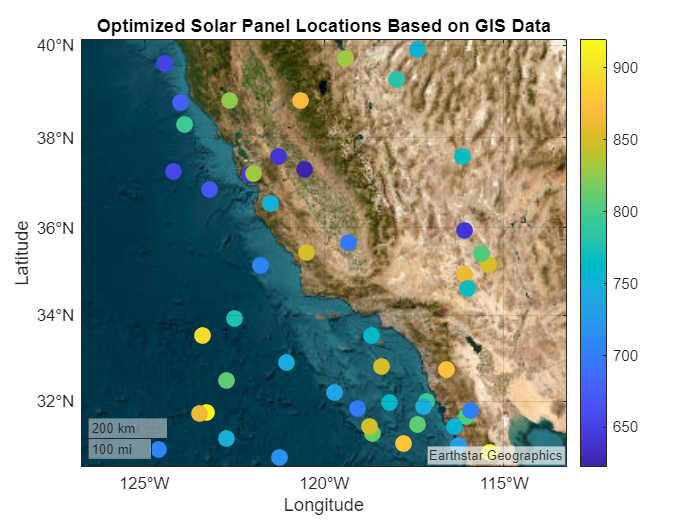


% Step 8: GIS Mapping: Visualizing Optimal Solar Panel Locations
figure;
geoscatter(latitude, longitude, 100, effective_irradiance, 'filled'); % Plot points
geobasemap satellite; % Use satellite map for better visualization
title('Optimized Solar Panel Locations Based on GIS Data');
colorbar; % Show color scale for irradiance intensity


%% Step 9: IoT Sensor Integration (Simulated)
% Simulate real-time IoT sensor data (Replace with actual sensor input)
iot_solar_irradiance = 850 + randn() * 10; % Simulated irradiance data (W/m²)
iot_temperature = 30 + randn() * 2; % Simulated temperature data (°C)

fprintf('IoT Sensor - Solar Irradiance: %.2f W/m² | Temperature: %.2f°C\n', iot_solar_irradiance, iot_temperature);

IoT Sensor - Solar Irradiance: 853.19 W/m² | Temperature: 27.38°C



%% Step 10: Smart Tracking System (Dynamic Panel Rotation)
function new_tilt = adjustTilt(current_irradiance)
    % Adjust panel tilt dynamically based on solar irradiance
    if current_irradiance < 800
        new_tilt = 5; % Increase tilt for better exposure
    elseif current_irradiance > 900
        new_tilt = -5; % Reduce tilt for optimal output
    else
        new_tilt = 0; % Maintain current tilt
    end
end

% Adjust tilt based on simulated IoT sensor data
panel_tilt_adjustment = adjustTilt(iot_solar_irradiance);
fprintf('Adjusted Panel Tilt: %d°\n', panel_tilt_adjustment);

Adjusted Panel Tilt: 0°
